# A von Karman plate with 1:1 internal resonance

In this example, we consider a simply-supported von Karman square plate subject to harmonic excitation. Due to the geometric symmetry, the natural frequenices of the second and the third modes are the same. In other words, the system has 1:1 internal resonance between the two modes. We extract the forced response curve using SSM reduction. In  this notebook, we focus on quasi-periodic response of the system.

## Geometry and finite element model

We discretize the plate with 400 elements and then 2406 degrees-of-freedom. The dimension of the phase space of the full system is then 1212. As we will see, the reduced-order model obtained by SSM reduction is four dimensional.

Building FE model


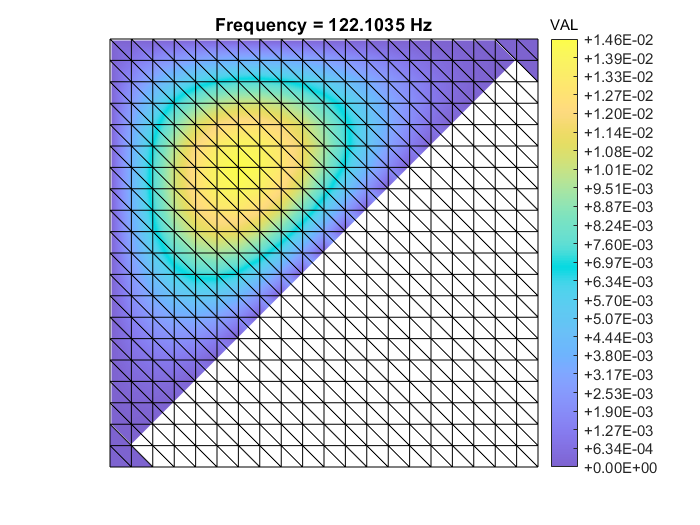

Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem
The circular natural frequencies of the first five modes:


omega = 	1.0e+03 *

    0.3072
    0.7672
    0.7682
    1.2268
    1.5352


Using Rayleigh damping
Getting nonlinearity coefficients
Assembling Tensors
Saving Tensors
Assembling external force vector


clear all; close all; clc

l = 1; % length of domain [m]
b = 1;  % breadth of domain [m]
t = 1e-2; % thickness of plate [m]
w = 0.0; % curvature parameter (height of the midpoint relative to ends) [m]
% material properties
E     = 70e9;  % 70e9 % 200e9 % Young's modulus [Pa]
rho   = 2700; % 2700 % 7850 % density [kg/m^3]
nu    = 0.33;    % Poisson's ratio 
kappa = 1e5; % material damping modulus 1e8

% Mesh
nElements = 20;
nl = nElements;
nb = nElements;
bc = 'SSSS';
startFE = tic;
[M,C,K,fnl,~,outdof] = build_model(l,b,t,w,E,rho,nu,kappa,bc,nl,nb);

timeFE = toc(startFE);
varargout{1} = timeFE;
n  = length(M);

## Dynamical System Setup

notation = 'multiindex';
DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',5,'Nmax',10,'notation',notation);

## Linear Modal analysis

[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.242038e-03
modal damping ratio for 2 mode is 2.186120e-03
modal damping ratio for 3 mode is 2.187285e-03
modal damping ratio for 4 mode is 2.861091e-03
modal damping ratio for 5 mode is 3.396085e-03
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 10 eigenvalues are given as 
   1.0e+03 *

  -0.0007 + 0.3072i
  -0.0007 - 0.3072i
  -0.0017 + 0.7672i
  -0.0017 - 0.7672i
  -0.0017 + 0.7682i
  -0.0017 - 0.7682i
  -0.0035 + 1.2268i
  -0.0035 - 1.2268i
  -0.0052 + 1.5352i
  -0.0052 - 1.5352i



## Add forcing

f_0 = zeros(n,1);
f_0(outdof(1)) = 100;
kappas  = [-1; 1];
epsilon = 0.5;
coeffs  = epsilon * [f_0 f_0]/2;
DS.add_forcing(coeffs, kappas);

## Primiary resonance with IRs

**Create SSM**

S = SSM(DS);
set(S.Options, 'reltol', 0.8,'notation',notation); % 0.8 is used

**Extract FRC for periodic orbits**

(near) outer resonance detected for the following combination of master eigenvalues
     0     0     1     1
     0     1     1     0
     1     0     0     1
     1     1     0     0
     0     0     2     1
     0     1     2     0
     1     0     1     1
     1     1     1     0
     2     0     0     1
     2     1     0     0
     0     0     1     1
     0     1     1     0
     1     0     0     1
     1     1     0     0
     0     0     1     2
     0     1     1     1
     0     2     1     0
     1     0     0     2
     1     1     0     1
     1     2     0     0
     0     0     2     0
     1     0     1     0
     2     0     0     0
     0     0     2     1
     0     1     2     0
     1     0     1     1
     1     1     1     0
     2     0     0     1
     2     1     0     0
     0     0     0     2
     0     1     0     1
     0     2     0     0
     0     0     1     2
     0     1     1     1
     0     2     1     0
     1     0     0     2
     1     1    

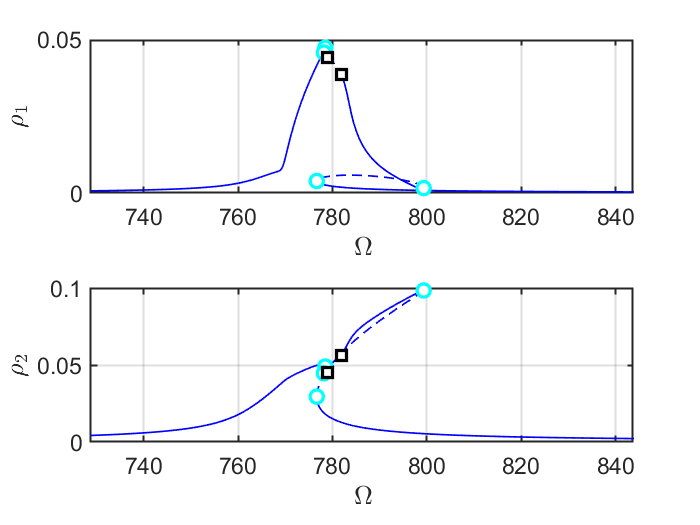

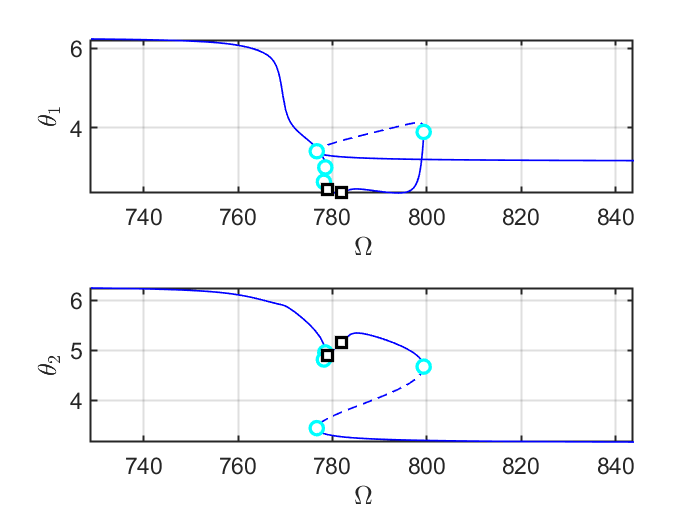

the forcing frequency 7.2884e+02 is nearly resonant with the eigenvalue -1.6772e+00 + i7.6720e+02
the forcing frequency 7.2950e+02 is nearly resonant with the eigenvalue -1.6772e+00 + i7.6720e+02
the forcing frequency 7.3070e+02 is nearly resonant with the eigenvalue -1.6772e+00 + i7.6720e+02
the forcing frequency 7.3180e+02 is nearly resonant with the eigenvalue -1.6772e+00 + i7.6720e+02
the forcing frequency 7.3296e+02 is nearly resonant with the eigenvalue -1.6772e+00 + i7.6720e+02
the forcing frequency 7.3402e+02 is nearly resonant with the eigenvalue -1.6772e+00 + i7.6720e+02
the forcing frequency 7.3515e+02 is nearly resonant with the eigenvalue -1.6772e+00 + i7.6720e+02
the forcing frequency 7.3618e+02 is nearly resonant with the eigenvalue -1.6772e+00 + i7.6720e+02
the forcing frequency 7.3727e+02 is nearly resonant with the eigenvalue -1.6772e+00 + i7.6720e+02
the forcing frequency 7.3827e+02 is nearly resonant with the eigenvalue -1.6772e+00 + i7.6720e+02
the forcing frequenc

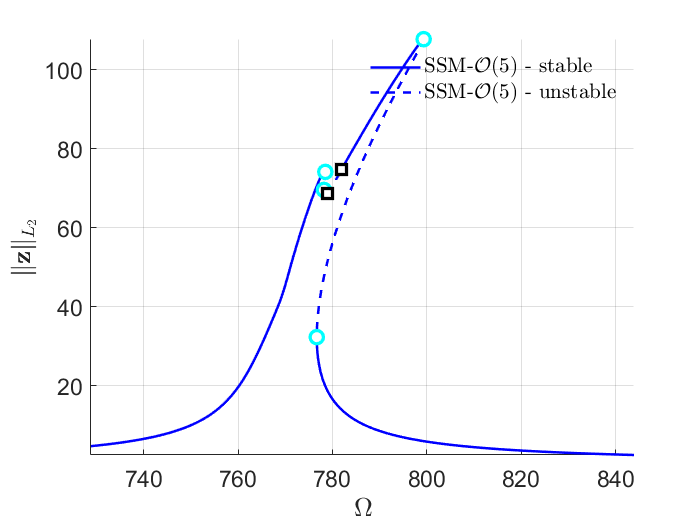

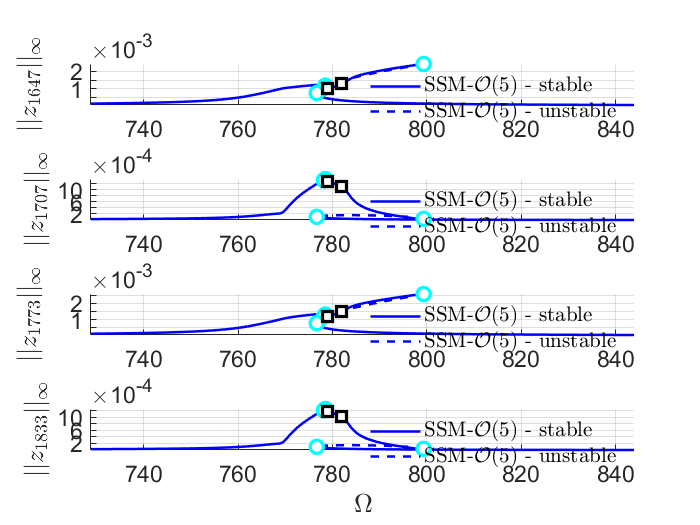

set(S.FRCOptions, 'omegaSampStyle','cocoBD');
set(S.contOptions, 'PtMX', 2000, 'h_max', 5, 'h_min', 1e-4);
set(S.FRCOptions, 'initialSolver', 'fsolve');
freqrange = [0.95 1.1]*imag(D(3));
order     = 5;
resonant_modes = [3 4 5 6];
mFreq   = [1 1];
FRC = S.SSM_isol2ep('isol_polar',resonant_modes, order, mFreq, 'freq', freqrange,outdof);

**Extract FRC for quasi-periodic orbits**


 Run='po.po': Continue periodic orbits born from HB point.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          6.12e-06  1.11e+03    0.0    0.0    0.0
   1   1  1.00e+00  2.17e-05  1.11e-11  1.11e+03    0.0    0.0    0.0
   2   1  1.00e+00  2.45e-10  1.87e-14  1.11e+03    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om    po.period          eps
    0  00:00:00   1.1065e+03      1  EP      7.8190e+02   1.7192e+00   1.0000e+00
    1  00:00:00   1.1065e+03      2  FP      7.8190e+02   1.7192e+00   1.0000e+00
    2  00:00:00   1.1065e+03      3  BP      7.8189e+02   1.7193e+00   1.0000e+00
    2  00:00:00   1.1065e+03      4          7.8188e+02   1.7199e+00   1.0000e+00
    4  00:00:01   1.1064e+03      5          7.8185e+02   1.7220e+00   1.0000e+00
    6  00:00:01   1.1062e+03      6          7.8179e+02   1.7259e+00   1.0000e+00
    8  00:00:0

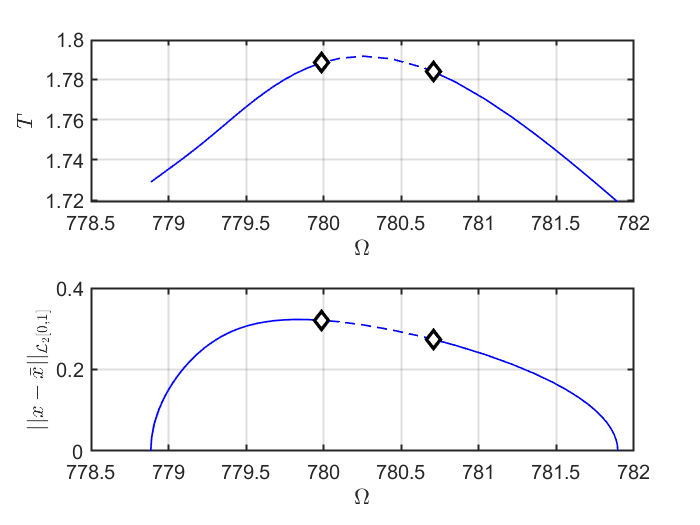

Constructing torus in reduced dynamical system
Interpolation at frequency 7.818955e+02
Interpolation at frequency 7.818955e+02
Interpolation at frequency 7.818929e+02
Interpolation at frequency 7.818849e+02
Interpolation at frequency 7.818521e+02
Interpolation at frequency 7.817943e+02
Interpolation at frequency 7.817057e+02
Interpolation at frequency 7.815687e+02
Interpolation at frequency 7.813617e+02
Interpolation at frequency 7.810452e+02
Interpolation at frequency 7.807096e+02
Interpolation at frequency 7.806401e+02
Interpolation at frequency 7.802550e+02
Interpolation at frequency 7.799885e+02
Interpolation at frequency 7.799872e+02
Interpolation at frequency 7.798091e+02
Interpolation at frequency 7.796779e+02
Interpolation at frequency 7.795704e+02
Interpolation at frequency 7.794739e+02
Interpolation at frequency 7.793808e+02
Interpolation at frequency 7.792856e+02
Interpolation at frequency 7.791844e+02
Interpolation at frequency 7.790783e+02
Interpolation at frequency 7.7897

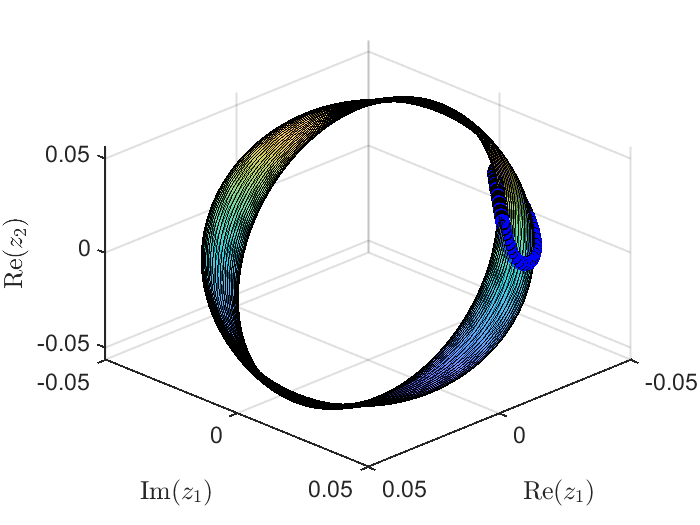

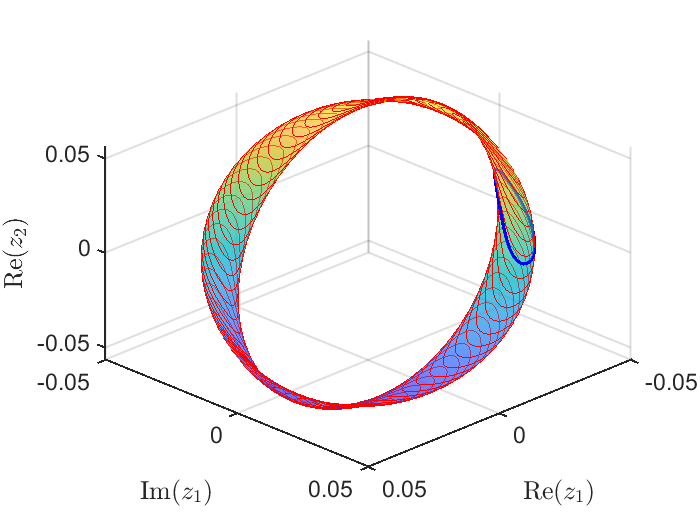


 FRCs from ='po.po': generating torus in physical domain.


set(S.contOptions, 'PtMX',50,'NAdapt',2, 'bi_direct',false,'NSV',2);
HBlab = 20;
S.SSM_HB2po('po','isol_polar',HBlab,'freq',freqrange,[outdof;outdof+n],'saveICs');

Plot of FRC for quasi-periodic orbits

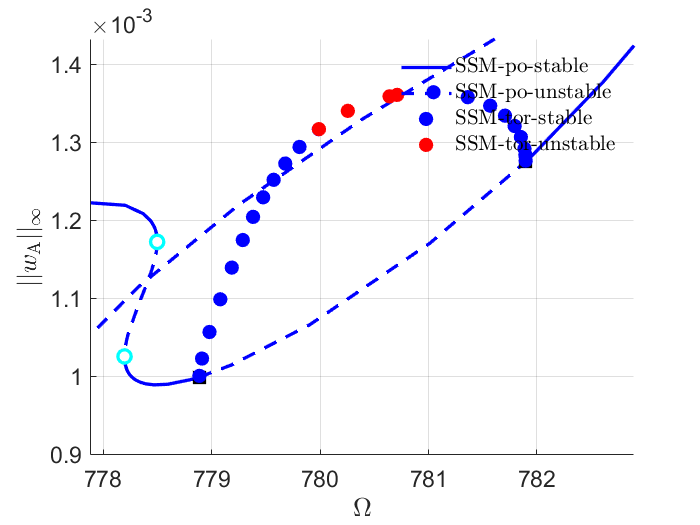

% calculate response amplitude of quasi-periodic orbits
bd   = coco_bd_read('po.po');
lab  = coco_bd_labs(bd, 'FP');
lab  = max(lab);
labs = [1,3:lab-1];
lab  = numel(labs);
x1_tr = zeros(lab,1);
x2_tr = zeros(lab,1);
om_tr = zeros(lab,1);
st    = false(lab,1);
for i=1:lab
    sol = SSM_po_read_solution('po',labs(i));
    st(i)    = sol.st;
    om_tr(i) = sol.om;
    x1i      = sol.xTr(:,1,:);
    x2i      = sol.xTr(:,2,:);
    x1_tr(i) = norm(x1i(:),'inf');
    x2_tr(i) = norm(x2i(:),'inf');
end


% background periodic response
% plot results of periodic reponse and tori in the same figure
ST = cell(2,1);
ST{1} = {'b--','LineWidth',2}; % unstable
ST{2} = {'b-','LineWidth',2};  % stable
legs = 'SSM-po-unstable';
legu = 'SSM-po-stable';
thm = struct();
thm.SN = {'LineStyle', 'none', 'LineWidth', 2, ...
  'Color', 'cyan', 'Marker', 'o', 'MarkerSize', 8, 'MarkerEdgeColor', ...
  'cyan', 'MarkerFaceColor', 'white'};
thm.HB = {'LineStyle', 'none', 'LineWidth', 2, ...
  'Color', 'black', 'Marker', 's', 'MarkerSize', 8, 'MarkerEdgeColor', ...
  'black', 'MarkerFaceColor', 'white'};

SNidx = FRC.SNidx;
HBidx = FRC.HBidx;
FRC.st = double(FRC.st);
FRC.st(HBidx) = nan;
FRC.st(SNidx) = nan;

figure; hold on
plot_stab_lines(FRC.om,FRC.Aout_frc(:,1),FRC.st,ST,legs,legu);
SNfig = plot(FRC.om(SNidx),FRC.Aout_frc(SNidx,1),thm.SN{:});
set(get(get(SNfig,'Annotation'),'LegendInformation'),...
'IconDisplayStyle','off');
HBfig = plot(FRC.om(HBidx),FRC.Aout_frc(HBidx,1),thm.HB{:});
set(get(get(HBfig,'Annotation'),'LegendInformation'),...
'IconDisplayStyle','off');   
xlabel('$\Omega$','Interpreter','latex'); 
ylabel('$||w_\mathrm{A}||_{\infty}$','Interpreter','latex'); 
set(gca,'FontSize',14);
grid on, axis tight; 
legend boxoff;
fig1 = gcf;

figure; hold on
plot_stab_lines(FRC.om,FRC.Aout_frc(:,2),FRC.st,ST,legs,legu);
SNfig = plot(FRC.om(SNidx),FRC.Aout_frc(SNidx,2),thm.SN{:});
set(get(get(SNfig,'Annotation'),'LegendInformation'),...
'IconDisplayStyle','off');
HBfig = plot(FRC.om(HBidx),FRC.Aout_frc(HBidx,2),thm.HB{:});
set(get(get(HBfig,'Annotation'),'LegendInformation'),...
'IconDisplayStyle','off');   
xlabel('$\Omega$','Interpreter','latex'); 
ylabel('$||w_\mathrm{B}||_{\infty}$','Interpreter','latex'); 
set(gca,'FontSize',14);
grid on; axis tight; 
fig2 = gcf;

% plot results of quasi-periodic orbits
figure(fig1); hold on
plot(om_tr(st), x1_tr(st), 'o','MarkerSize', 8, 'MarkerEdgeColor', ...
  'blue', 'MarkerFaceColor', 'blue','DisplayName','SSM-tor-stable');
plot(om_tr(~st), x1_tr(~st), 'o','MarkerSize', 8, 'MarkerEdgeColor', ...
  'red', 'MarkerFaceColor', 'red','DisplayName','SSM-tor-unstable');
lowb = 0.9*min(FRC.Aout_frc(HBidx,1));
upb  = 1.05*max(x1_tr);
axis([min(FRC.om(HBidx))-1,max(FRC.om(HBidx))+1,lowb,upb]);

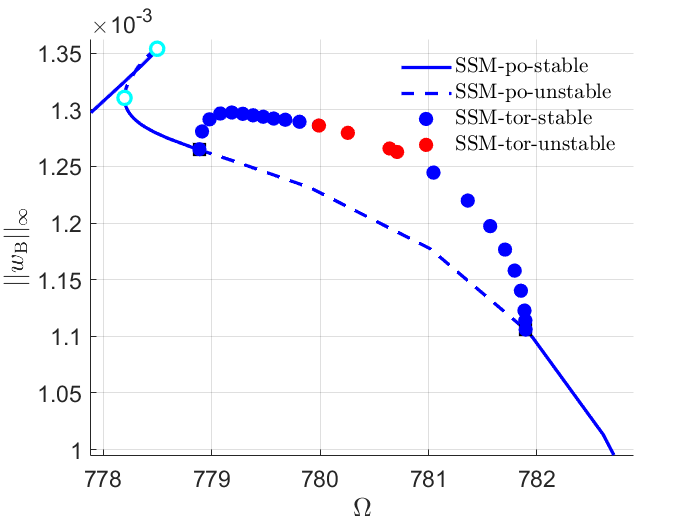

figure(fig2); hold on
plot(om_tr(st), x2_tr(st), 'o','MarkerSize', 8, 'MarkerEdgeColor', ...
  'blue', 'MarkerFaceColor', 'blue','DisplayName','SSM-tor-stable');
plot(om_tr(~st), x2_tr(~st), 'o','MarkerSize', 8, 'MarkerEdgeColor', ...
  'red', 'MarkerFaceColor', 'red','DisplayName','SSM-tor-unstable');
lowb = 0.9*min(FRC.Aout_frc(HBidx,2));
upb  = 1.05*max(x2_tr);
axis([min(FRC.om(HBidx))-1,max(FRC.om(HBidx))+1,lowb,upb]);
set(gca,'FontSize',14);
legend boxoff;

**Exercises**

- Use SSM_isol2ep to calculate the forced response curve with varied forcing amplitude $\epsilon$.

- Use SSM_ep2SN to locate the solution manifold of saddle-node bifurcation periodic orbits.

- Use SSM_ep2HB to locate the solution manifold of torus bifurcation periodic orbits.